# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 2019-07-02 08:13:21

## Create the Layer Graph

Create the layer graph variable to contain the network's layers.

lgraph = layerGraph();

## Add the Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([16 16 1],"Name","imageinput")
    convolution2dLayer([3 3],64,"Name","Encoder-Stage-1-Conv-1","Padding","same")
    reluLayer("Name","Encoder-Stage-1-ReLU-1")
    convolution2dLayer([3 3],64,"Name","Encoder-Stage-1-Conv-2","Padding","same")
    reluLayer("Name","Encoder-Stage-1-ReLU-2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","Encoder-Stage-1-MaxPool-1","Stride",[2 2])
    convolution2dLayer([3 3],128,"Name","Encoder-Stage-2-Conv-1","Padding","same")
    reluLayer("Name","Encoder-Stage-2-ReLU-1")
    convolution2dLayer([3 3],128,"Name","Encoder-Stage-2-Conv-2","Padding","same")
    reluLayer("Name","Encoder-Stage-2-ReLU-2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    maxPooling2dLayer([2 2],"Name","Encoder-Stage-2-MaxPool-1","Stride",[2 2])
    convolution2dLayer([3 3],256,"Name","Encoder-Stage-3-Conv-1","Padding","same")
    reluLayer("Name","Encoder-Stage-3-ReLU-1")
    convolution2dLayer([3 3],256,"Name","Encoder-Stage-3-Conv-2","Padding","same")
    reluLayer("Name","Encoder-Stage-3-ReLU-2")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    dropoutLayer(0.5,"Name","Encoder-Stage-3-DropOut-1")
    maxPooling2dLayer([2 2],"Name","Encoder-Stage-3-MaxPool-1","Stride",[2 2])
    convolution2dLayer([3 3],512,"Name","Bridge-Conv-1","Padding","same")
    reluLayer("Name","Bridge-ReLU-1")
    convolution2dLayer([3 3],512,"Name","Bridge-Conv-2","Padding","same")
    reluLayer("Name","Bridge-ReLU-2")
    dropoutLayer(0.5,"Name","Bridge-DropOut-1")
    transposedConv2dLayer([2 2],256,"Name","Decoder-Stage-1-UpConv","Stride",[2 2])
    reluLayer("Name","Decoder-Stage-1-UpReLU")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","Decoder-Stage-1-DepthConcatenation")
    convolution2dLayer([3 3],256,"Name","Dcoder-Stage-1-Conv-1","Padding","same")
    reluLayer("Name","Decoder-Stage-1-ReLU-1")
    convolution2dLayer([3 3],256,"Name","Decoder-Stage-1-Conv-2","Padding","same")
    reluLayer("Name","Decoder-Stage-1-ReLU-2")
    transposedConv2dLayer([2 2],128,"Name","Decoder-Stage-2-UpConv","Stride",[2 2])
    reluLayer("Name","Decoder-Stage-2-UpReLU")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","Decoder-Stage-2-DepthConcatenation")
    convolution2dLayer([3 3],128,"Name","Dcoder-Stage-2-Conv-1","Padding","same")
    reluLayer("Name","Decoder-Stage-2-ReLU-1")
    convolution2dLayer([3 3],128,"Name","Decoder-Stage-2-Conv-2","Padding","same")
    reluLayer("Name","Decoder-Stage-2-ReLU-2")
    transposedConv2dLayer([2 2],64,"Name","Decoder-Stage-3-UpConv","Stride",[2 2])
    reluLayer("Name","Decoder-Stage-3-UpReLU")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    depthConcatenationLayer(2,"Name","Decoder-Stage-3-DepthConcatenation")
    convolution2dLayer([3 3],64,"Name","Dcoder-Stage-3-Conv-1","Padding","same")
    reluLayer("Name","Decoder-Stage-3-ReLU-1")
    convolution2dLayer([3 3],64,"Name","Decoder-Stage-3-Conv-2","Padding","same")
    reluLayer("Name","Decoder-Stage-3-ReLU-2")
    convolution2dLayer([1 1],64,"Name","Final-ConvolutionLayer")
    regressionLayer("Name","regressionLayer")];
lgraph = addLayers(lgraph,tempLayers);

## Connect the Layer Branches

Connect all the branches of the network to create the network's graph.

lgraph = connectLayers(lgraph,"Encoder-Stage-1-ReLU-2","Encoder-Stage-1-MaxPool-1");
lgraph = connectLayers(lgraph,"Encoder-Stage-1-ReLU-2","Decoder-Stage-3-DepthConcatenation/in2");
lgraph = connectLayers(lgraph,"Encoder-Stage-2-ReLU-2","Encoder-Stage-2-MaxPool-1");
lgraph = connectLayers(lgraph,"Encoder-Stage-2-ReLU-2","Decoder-Stage-2-DepthConcatenation/in2");
lgraph = connectLayers(lgraph,"Encoder-Stage-3-ReLU-2","Encoder-Stage-3-DropOut-1");
lgraph = connectLayers(lgraph,"Encoder-Stage-3-ReLU-2","Decoder-Stage-1-DepthConcatenation/in2");
lgraph = connectLayers(lgraph,"Decoder-Stage-1-UpReLU","Decoder-Stage-1-DepthConcatenation/in1");
lgraph = connectLayers(lgraph,"Decoder-Stage-2-UpReLU","Decoder-Stage-2-DepthConcatenation/in1");
lgraph = connectLayers(lgraph,"Decoder-Stage-3-UpReLU","Decoder-Stage-3-DepthConcatenation/in1");

## Clean Up Helper Variable

clear tempLayers;

## Plot the Layers

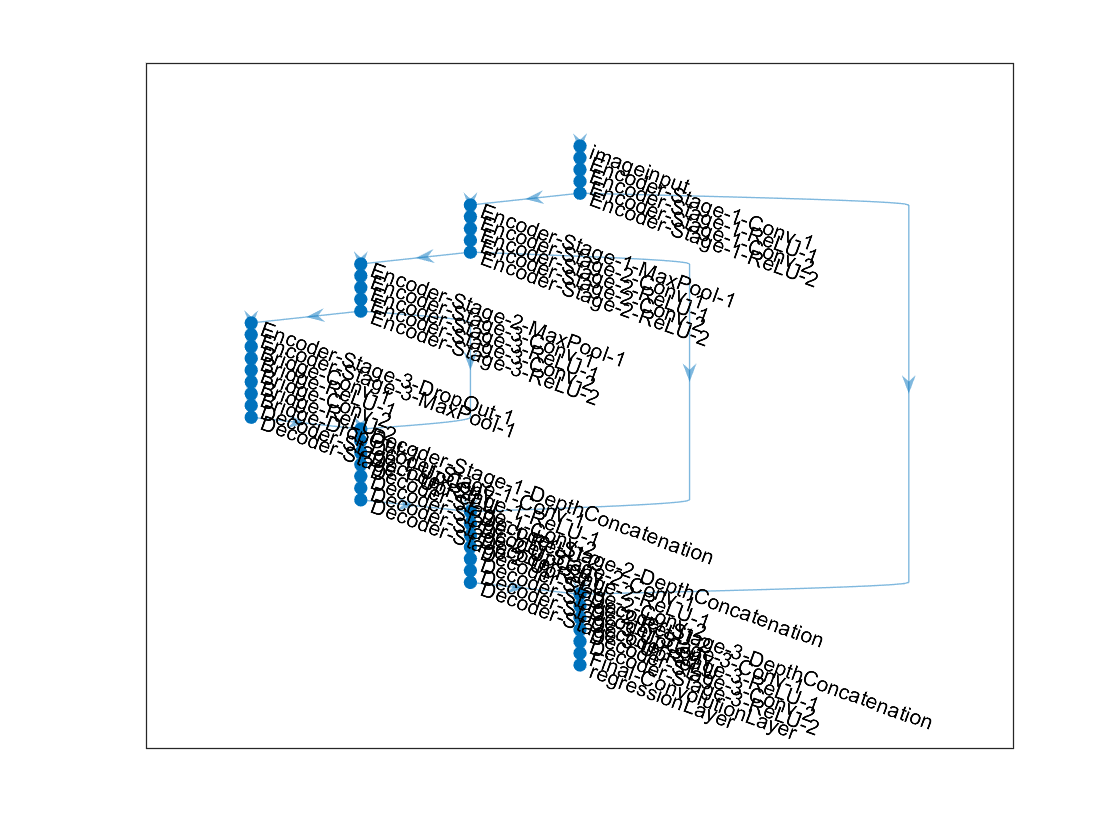

plot(lgraph);